# Continuous Feedback System for 2 DoF Manipulator

Add Path

clear;clc;
close all
addpath("Dynamics\")
addpath("..\ReadYAML\")
Robot=ReadYaml("Configuration\Jiang.yaml");
config=ReadYaml("Configuration\2DoF_Manipulator.yaml");

The system follows


$$M\left(\vec{q}\right) \ddot{\vec{q}} + C \left( \vec{q}, \dot{\vec{q}} \right) \dot{\vec{q}} + G \left( \vec{q} \right) = - K_{p} \left( \vec{q} - \vec{q}_{d} \right) - K_{d} \dot{\vec{q}} - f \left( \dot{\vec{q}} \right),$$


where friction follows the Stribeck model as


$$f(\dot{q}_{j})= \mathrm{sgn} \left( \dot{q}_{j} \right) \cdot \left[ F_{j}^{c} + F_{j}^{s} \exp{\left( - K_{j}^{s} \frac{\dot{q}_{j}}{V_{j}^{s}} \right)} \right] + F_{j}^{v} \dot{q}_{j}.$$


## Configurations

Sampling Time, Time Step & Simulation Time

dt=1e-5;
SimulationTime=config.SimulationTime;
TimeSpan=0:dt:SimulationTime;

Initial Condition

TargetAngle=config.TargetAngle';
StateInitial=config.StateInitial';

Gains

Kp=diag(config.Kp);
Kd=diag(config.Kd);

Time History Matrix

TorqueTimeHistoryContinuous=zeros(2, ...
    round(SimulationTime/dt)+1);

Solver Option

option=odeset('RelTol', config.ODE_RelTol, ...
    'AbsTol', config.ODE_AbsTol);

### Continuous Time Case

Simulation

tic
[t,State]=ode45(@(t,State)ODE(t,State,Robot,"Sigmoid" ...
    ,PDTorque(Kp,Kd,Robot,State,TargetAngle)), ...
    TimeSpan,StateInitial,option);
StateTimeHistoryContinuous=State';
for i=1:round(SimulationTime/dt)+1
    TorqueTimeHistoryContinuous(:,i)=PDTorque( ...
        Kp,Kd,Robot,StateTimeHistoryContinuous(:,i),TargetAngle);
end
toc

历时 2.576323 秒。


### Visualization for Continuous Time Control

Collect Data for Visualization

eTimeHistoryContinuous=StateTimeHistoryContinuous(1:2,:)-TargetAngle;

$e-t$ Diagram

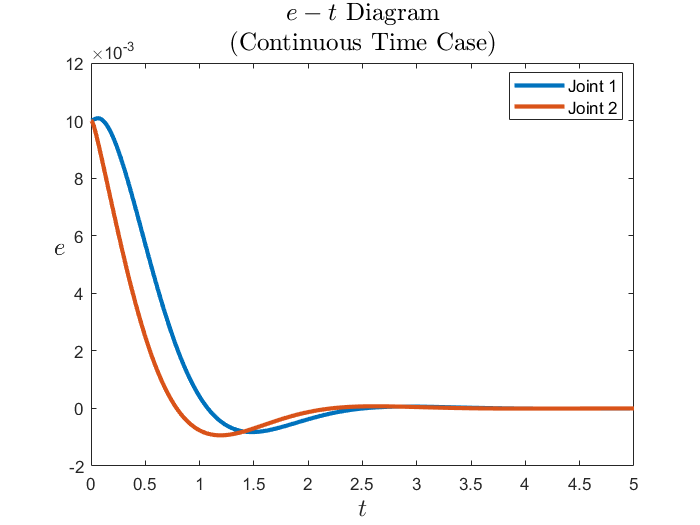

plot(TimeSpan,eTimeHistoryContinuous,"LineWidth",2.5)
title(["$$e-t$$ Diagram","(Continuous Time Case)"],"FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$e$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Fontsize",10,"Location","best")

$\dot{e}-t$ Diagram

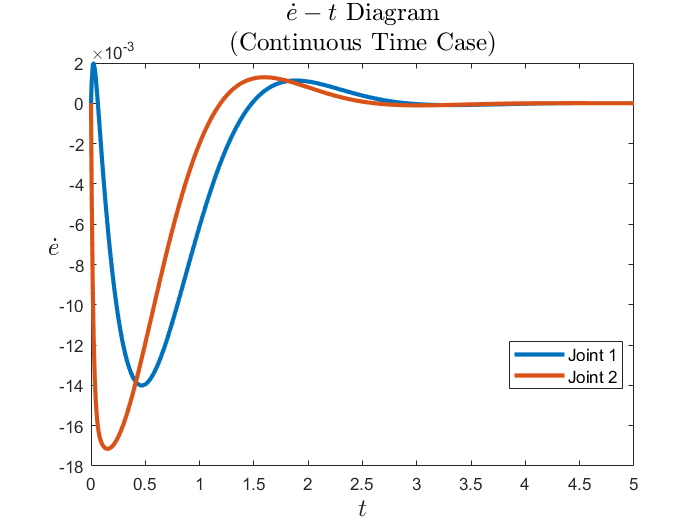

plot(TimeSpan,StateTimeHistoryContinuous(3:4,:),"LineWidth",2.5)
title(["$$\dot{e}-t$$ Diagram","(Continuous Time Case)"],"FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{e}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Fontsize",10,"Location","best")

$\tau-t$ Diagram

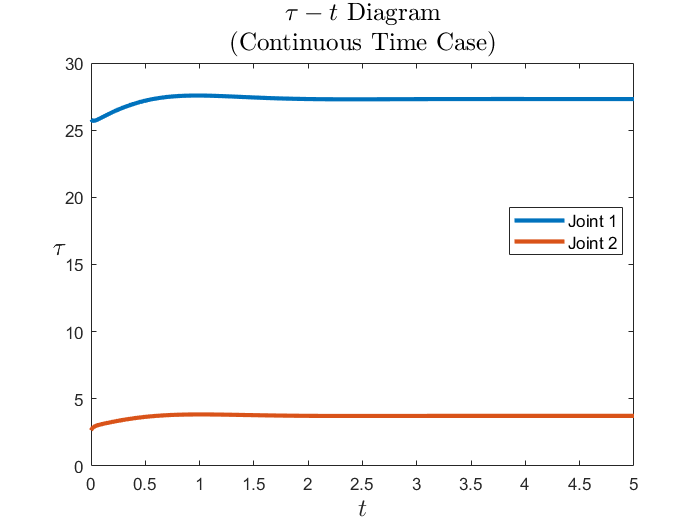

plot(TimeSpan,TorqueTimeHistoryContinuous,"LineWidth",2.5)
title(["$$\tau-t$$ Diagram","(Continuous Time Case)"],"FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\tau$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Fontsize",10,"Location","best")

## Save Data

save("Data\StateTimeHistory_Continuous_"+ ...
    datestr(datetime("today"),"yyyy_mm_dd")+".mat","StateTimeHistoryContinuous")

Remove Path

rmpath("Dynamics\")
rmpath("..\ReadYAML\")